clc; clear variables;

### QR Decompositions

Reconstruction and Orthogonality erros on random matrices in increasing size. 

import java.util.ArrayList;
Matrices = ArrayList();
MatrixSizes = 100: 100: 1000;
for I = MatrixSizes
    Matrices.add(rand(I));
end
[OrthErrs, RestrucErrs] = PerformenceSubroutine(Matrices,{@ModifiedGS, @qr, @QRFactorFromClass});


Plotting the Errors

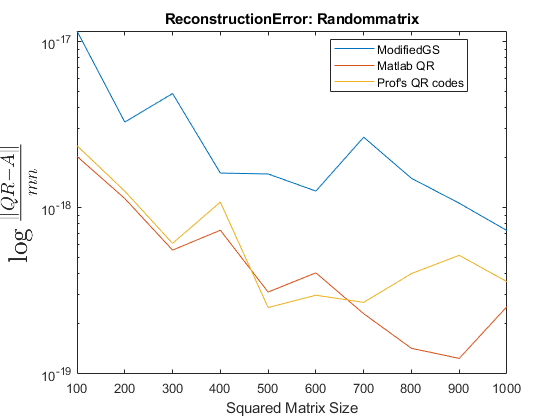

figure;
semilogy(MatrixSizes, RestrucErrs(1, :)); 
hold on;
semilogy(MatrixSizes, RestrucErrs(2, :)); 
semilogy(MatrixSizes, RestrucErrs(3, :)); 
title("ReconstructionError: Randommatrix");
legend("ModifiedGS", "Matlab QR", "Prof's QR codes", "location", "best");
xlabel("Squared Matrix Size");
ylabel("$\log{\frac{\Vert QR - A \Vert}{mn}}$", "interpreter", "latex", "FontSize", 20);
saveas(gcf, "ReconstructionError Randommatrix", "png");

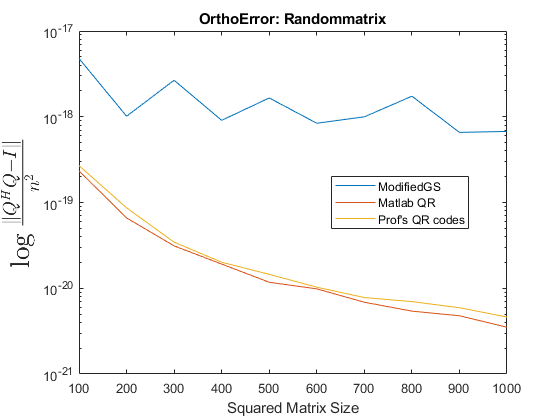


figure;
semilogy(MatrixSizes, OrthErrs(1, :)); 
hold on;
semilogy(MatrixSizes, OrthErrs(2, :)); 
semilogy(MatrixSizes, OrthErrs(3, :)); 
title("OrthoError: Randommatrix");
legend("ModifiedGS", "Matlab QR", "Prof's QR codes", "location", "best");
xlabel("Squared Matrix Size");
ylabel("$\log{\frac{\Vert Q^HQ - I \Vert}{n^2}}$", "interpreter", "latex", "FontSize", 20);
saveas(gcf, "OrthogonalityError Randommatrix", "png");

#### Pertubated Low Rank Matrix for accurancy testing 

import java.util.ArrayList;
Matrices = ArrayList();
MatrixSizes = 10: 100;
for I = MatrixSizes
    Matrices.add(1./(1:I)'*(1:I) + rand(I)*1e-14);
end
[OrthErrs, RestrucErrs] = PerformenceSubroutine(Matrices,{@ModifiedGS, @qr, @QRFactorFromClass});


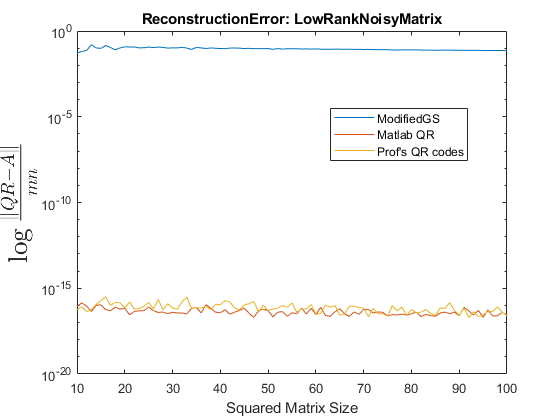


figure;
semilogy(MatrixSizes, RestrucErrs(1, :)); 
hold on;
semilogy(MatrixSizes, RestrucErrs(2, :)); 
semilogy(MatrixSizes, RestrucErrs(3, :)); 
title("ReconstructionError: LowRankNoisyMatrix");
legend("ModifiedGS", "Matlab QR", "Prof's QR codes", "location", "best");
xlabel("Squared Matrix Size");
ylabel("$\log{\frac{\Vert QR - A \Vert}{mn}}$", "interpreter", "latex", "FontSize", 20);
saveas(gcf, "ReconstructionError LowRankNoisyMatrix", "png");

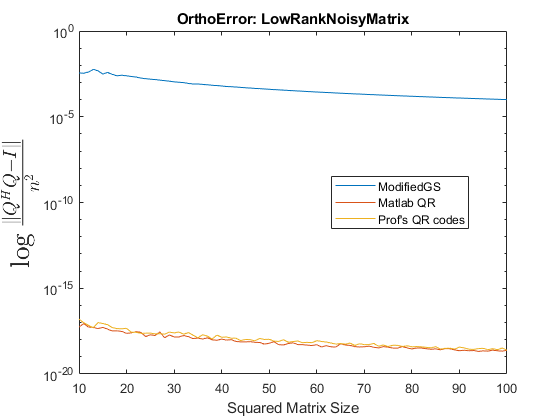


figure;
semilogy(MatrixSizes, OrthErrs(1, :)); 
hold on;
semilogy(MatrixSizes, OrthErrs(2, :)); 
semilogy(MatrixSizes, OrthErrs(3, :)); 
title("OrthoError: LowRankNoisyMatrix");
legend("ModifiedGS", "Matlab QR", "Prof's QR codes", "location", "best");
xlabel("Squared Matrix Size");
ylabel("$\log{\frac{\Vert Q^HQ - I \Vert}{n^2}}$", "interpreter", "latex", "FontSize", 20);
saveas(gcf, "OrthogonalityError LowRankNoisyMatrix", "png");

#### Hilbert Matrix Accuracy Testing

import java.util.ArrayList;
Matrices = ArrayList();
MatrixSizes = 10: 100;
for I = MatrixSizes
    [X, Y] = meshgrid(1:I);
    HilbertMatrix = 1./(X + Y);
    Matrices.add(HilbertMatrix);
end
[OrthErrs, RestrucErrs] = PerformenceSubroutine(Matrices,{@ModifiedGS, @qr, @QRFactorFromClass});

Plotting all of them out: 

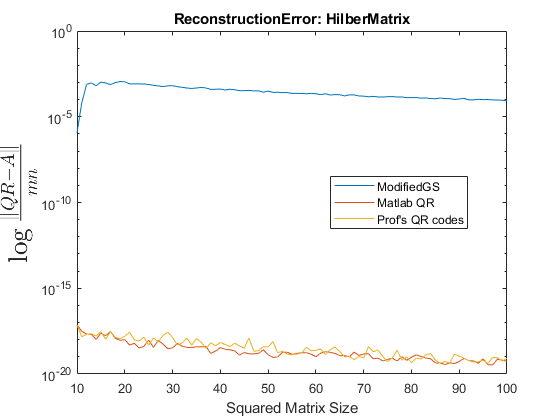

figure;
semilogy(MatrixSizes, RestrucErrs(1, :)); 
hold on;
semilogy(MatrixSizes, RestrucErrs(2, :)); 
semilogy(MatrixSizes, RestrucErrs(3, :)); 
title("ReconstructionError: HilberMatrix");
legend("ModifiedGS", "Matlab QR", "Prof's QR codes", "location", "best");
xlabel("Squared Matrix Size");
ylabel("$\log{\frac{\Vert QR - A \Vert}{mn}}$", "interpreter", "latex", "FontSize", 20);
saveas(gcf, "ReconstructionError HilberMatrix", "png");

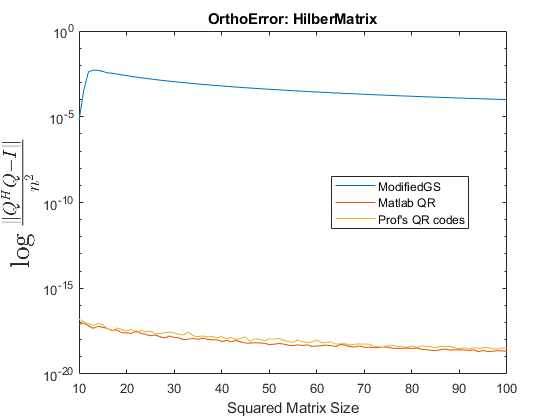


figure;
semilogy(MatrixSizes, OrthErrs(1, :)); 
hold on;
semilogy(MatrixSizes, OrthErrs(2, :)); 
semilogy(MatrixSizes, OrthErrs(3, :)); 
title("OrthoError: HilberMatrix");
legend("ModifiedGS", "Matlab QR", "Prof's QR codes", "location", "best");
xlabel("Squared Matrix Size");
ylabel("$\log{\frac{\Vert Q^HQ - I \Vert}{n^2}}$", "interpreter", "latex", "FontSize", 20);
saveas(gcf, "OrthogonalityError HilberMatrix", "png");

#### Vandermonde Matrix Accuracy Testing

import java.util.ArrayList;
Matrices = ArrayList();
MatrixSizes = 10: 100;
for I = MatrixSizes
    Matrices.add(vander(linspace(-2, 2, I)));
end
[OrthErrs, RestrucErrs] = PerformenceSubroutine(Matrices,{@ModifiedGS, @qr, @QRFactorFromClass});

Plotting things out: 

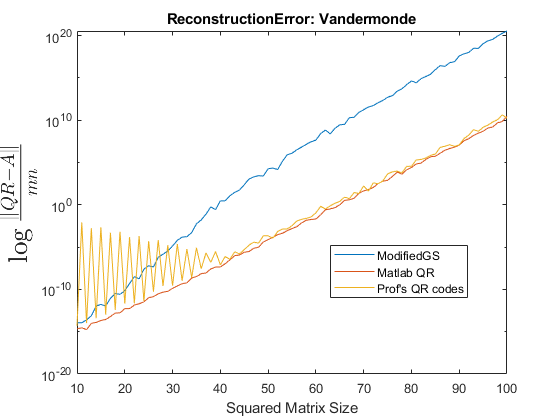

figure;
semilogy(MatrixSizes, RestrucErrs(1, :)); 
hold on;
semilogy(MatrixSizes, RestrucErrs(2, :)); 
semilogy(MatrixSizes, RestrucErrs(3, :)); 
title("ReconstructionError: Vandermonde");
legend("ModifiedGS", "Matlab QR", "Prof's QR codes", "location", "best");
xlabel("Squared Matrix Size");
ylabel("$\log{\frac{\Vert QR - A \Vert}{mn}}$", "interpreter", "latex", "FontSize", 20);
saveas(gcf, "ReconstructionError Vandermonde", "png");

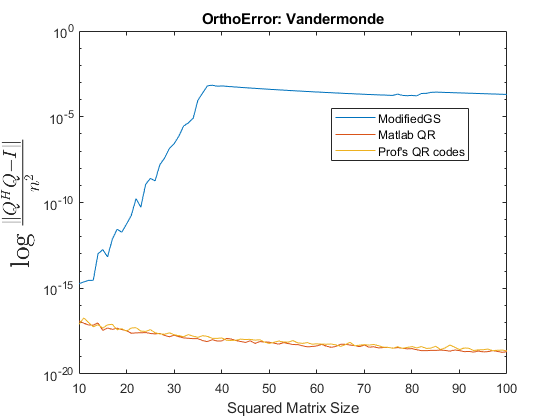


figure;
semilogy(MatrixSizes, OrthErrs(1, :)); 
hold on;
semilogy(MatrixSizes, OrthErrs(2, :)); 
semilogy(MatrixSizes, OrthErrs(3, :)); 
title("OrthoError: Vandermonde");
legend("ModifiedGS", "Matlab QR", "Prof's QR codes", "location", "best");
xlabel("Squared Matrix Size");
ylabel("$\log{\frac{\Vert Q^HQ - I \Vert}{n^2}}$", "interpreter", "latex", "FontSize", 20);
saveas(gcf, "OrthogonalityError Vandermonde", "png");

### Polynomials Conditioning

II (a), Plotting the badly conditioned polynomials: 

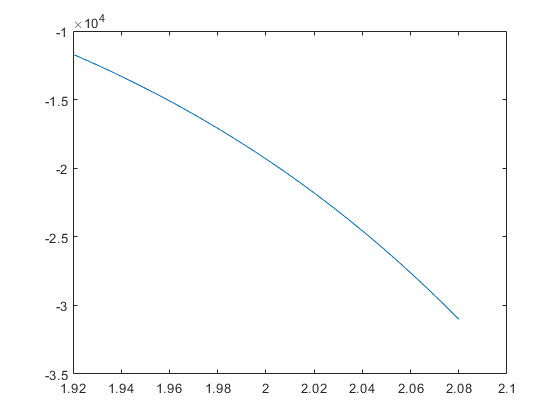

figure;
Xs = 1.920: 0.001: 2.08; 
plot(Xs, BadPolynomial(Xs))
saveas(gcf, "BadPolynomial.png", "png")

II (b), Plotting the goodly conditioned polynomials: 

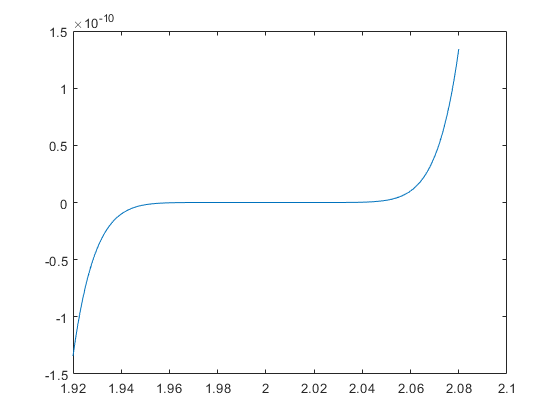


Xs = 1.920: 0.001: 2.08; 
plot(Xs, GoodPolynomial(Xs))
saveas(gcf, "GoodPolynomial.png", "png")

### Matrix Conditioning

#### (a) Condition number of a random matrix as the size increases. 

MatrixSizes = 1:10:1000;
ConditionNumbers = zeros(1, length(MatrixSizes));
for I = 1:length(MatrixSizes)
    ConditionNumbers(I) = cond(rand(MatrixSizes(I)));
end

Plotting it out: 

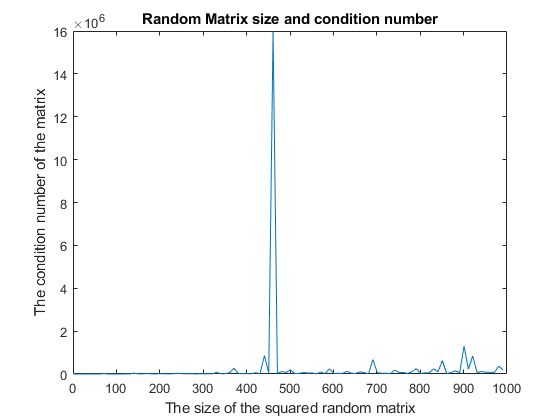

figure; 
plot(MatrixSizes, ConditionNumbers);
hold on;
title("Random Matrix size and condition number");
xlabel("The size of the squared random matrix");
ylabel("The condition number of the matrix");
saveas(gcf, "Random Matrix Size and their condition number", "png");

#### (b) Condition Number and Det of matrix when there is one repeating columns in the matrix. 

Condition number when there is one repeated column in the matrix.

RandomMatrix = rand(50, 49);
disp("The condition number of the matrix is: ")

The condition number of the matrix is: 


disp(cond(RandomMatrix));

   1.6825e+03



RandomMatrix(:, end + 1) = RandomMatrix(:, 1);
disp("The det after appending the first column to the right side gives: ");

The det after appending the first column to the right side gives: 


disp(det(RandomMatrix));

   2.6340e-12



disp("the condition of the new squared matrix with copied column is: ")

the condition of the new squared matrix with copied column is: 


disp(cond(RandomMatrix));

   1.4519e+17



The condition number is relatively huge, and it spikes after the modifications, the determinant is close to zero. 

Let's try a bigger matrix, and see if different things happen

RandomMatrix = rand(500, 499);
disp("The condition number of the matrix is: ")

The condition number of the matrix is: 


disp(cond(RandomMatrix));

   2.7008e+04



RandomMatrix(:, end + 1) = RandomMatrix(:, 1);
disp("The det after appending the first column to the right side gives: ");

The det after appending the first column to the right side gives: 


disp(det(RandomMatrix));

 -1.9022e+282



disp("the condition of the new squared matrix with copied column is: ")

the condition of the new squared matrix with copied column is: 


disp(cond(RandomMatrix));

   3.8722e+18



Observe that the condition number spikes up like before, but the determinant of the matrix is no where near zero when the matrix size is larger. 

#### (c) Condition Number as a function of noise for repeated column.  

NoiseLevel = -16: 1: -2;
NoiseLevel = 10.^NoiseLevel;
RandomMatrix = rand(50, 50);
ConditionNumbers = zeros(1, length(NoiseLevel));
for I = 1: length(NoiseLevel)
    RandomMatrix(:, end) = RandomMatrix(:, 1) + rand(50, 1)*NoiseLevel(I);
    ConditionNumbers(I) = cond(RandomMatrix);
end
figure;
loglog(NoiseLevel, ConditionNumbers, "ko");
title ("NoiseLevel and Condition Number");
xlabel("Amount of Gaussian Noise on the last repeated column");
ylabel("Condition Number");

Also, let's try to fit the line cause it seems pretty regular. 

p = polyfit(log10(NoiseLevel), log10(ConditionNumbers), 1);
disp("log log best fit slope: ")

log log best fit slope: 


disp(p(2))

    2.5681



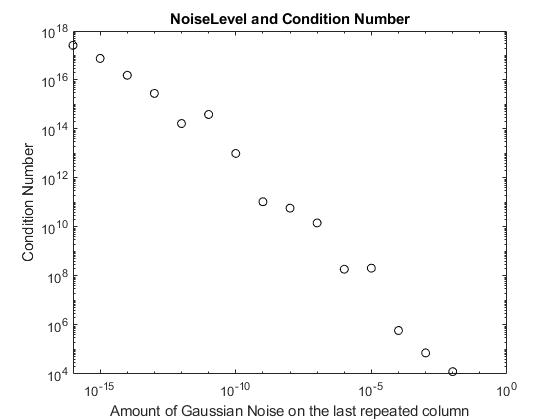

saveas(gcf, "Noise Level and Condition Number", "png");